**Abd Essalam AICHAOUI**

## `1. Code NMEA`

-Le code NMEA est un protocole de communication série utilisé pour le transfert de données entre des équipements électroniques, notamment les récepteurs GPS. Il est défini par la National Marine Electronics Association (NMEA) et est utilisé dans une large gamme d'applications marines, telles que la navigation, la pêche et la plaisance.

-Les phrases NMEA, également appelées trames NMEA, sont des messages ASCII qui contiennent des informations spécifiques sur les données de navigation. Chaque trame commence par le caractère '$' suivi d'une lettre identifiant le type de trame, suivi des données séparées par des virgules.

- `$GPGGA`(Global Positioning System Fix Data),`Récepteur GP:`:Cette trame fournit des informations sur la qualité du signal GPS, la latitude, la longitude, l'altitude et d'autres données liées à la position.

- `$GPGLL`(Geographic Position, Latitude/Longitude),`Récepteur GP:`:Cette trame fournit des données de position sous forme de latitude et longitude.

- `$GPVTG`(Course Over Ground and Ground Speed):Cette trame fournit des informations sur le cap et la vitesse par rapport au sol.

- `$GPZDA`(UTC Date and Time, Day, Month, Year),`Récepteur GP:`:Cette trame fournit des informations sur la date et l'heure en temps universel coordonné (UTC).

- `$SDDBS`(Echo Sounder Depth Below Surface),`Récepteur GP:`: Cette trame est utilisée pour transmettre des données liées à la profondeur sous la surface de l'eau depuis un échosondeur ou un récepteur de sondeur.Elle peut inclure des informations telles que la profondeur mesurée en pieds (f) ou en mètres (M).

-La fonction `nmealineread` permet de traiter différentes phrases NMEA et d'extraire des informations spécifiques de chacune d'elles pour les stocker dans une structure MATLAB appelée `data`. La structure de sortie varie en fonction du type de phrase NMEA traitée.

-La sortie de la fonction `nmealineread` est une structure MATLAB appelée `data`. Cette structure est conçue pour stocker des informations spécifiques extraites de la phrase NMEA donnée en entrée. La configuration précise de la structure `data` varie en fonction du type de phrase NMEA pris en considération.

-une description des structures de sortie pour chaque type de phrase NMEA pris en charge :

$GPGGA :

- `data.BODCTime` : Heure sous forme de fraction de jour.

- `data.latitude` : Latitude décimale au nord.

- `data.longitude` : Longitude décimale à l'est.

$GPGLL :

- `data.latitude` : Latitude décimale au nord.

- `data.longitude` : Longitude décimale à l'est.

- `data.BODCTime` : (éventuellement) Heure sous forme de fraction de jour.

$GPVTG :

- `data.truecourse` : Cap réel en degrés.

- `data.speed` : Vitesse par rapport au sol en nœuds.

$GPZDA :

- `data.BODCTime` : Numéro de jour.

- `data.offset` : L'offset (sous forme d'une fraction de jour) nécessaire pour générer l'heure locale à partir de BODCTime.

$SDDBS :

- `data.depth` : Profondeur de l'eau sous la surface (en mètres).

3)Le teste de la founction:

disp('Test de la founction pour l''extraction des donnees');

Test de la founction pour l'extraction des donnees


[data,ierr]  =  nmealineread('$GPGGA,074259.000,4846.9098,N,00205.9515,E,1,10,0.9,199.0,M,,,,0000*02')

data = struct with fields:
     BODCTime: 0.3215
     latitude: 48.7818
    longitude: 2.0992


ierr = 0

`-La fonction nmealineread a été exécutée avec succès sur la phrase NMEA fournie.`

`-Les données extraites sont affichées dans la structure 'data', et le code d'erreur 'ierr' indique qu'aucune erreur n'a été rencontrée.`

## `2.1 Extraction des données d'un itinéraire`

disp('L''itinéraire du fichier output.nmea:')

L'itinéraire du fichier output.nmea:


n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

n = 11

n = 12

n = 13

n = 14

n = 15

n = 16

n = 17

n = 18

n = 19

n = 20

n = 21

n = 22

n = 23

n = 24

n = 25

n = 26

n = 27

n = 28

n = 29

n = 30

n = 31

n = 32

n = 33

n = 34

n = 35

n = 36

n = 37

n = 38

n = 39

n = 40

n = 41

n = 42

n = 43

n = 44

n = 45

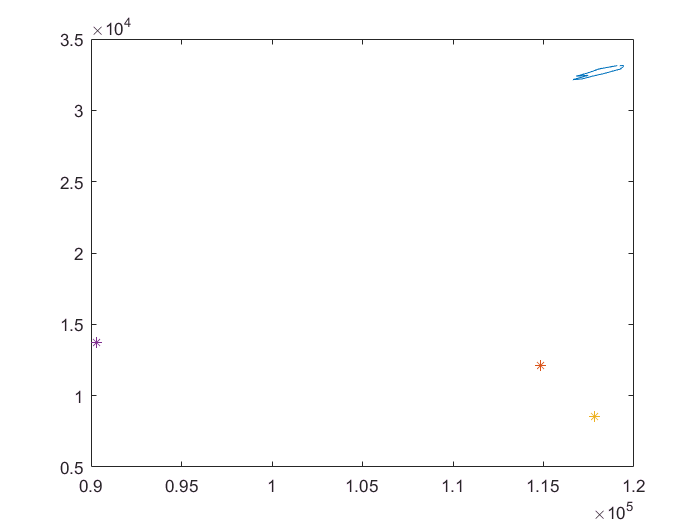

[latitude, longitude, X, Y] = trace_trace;

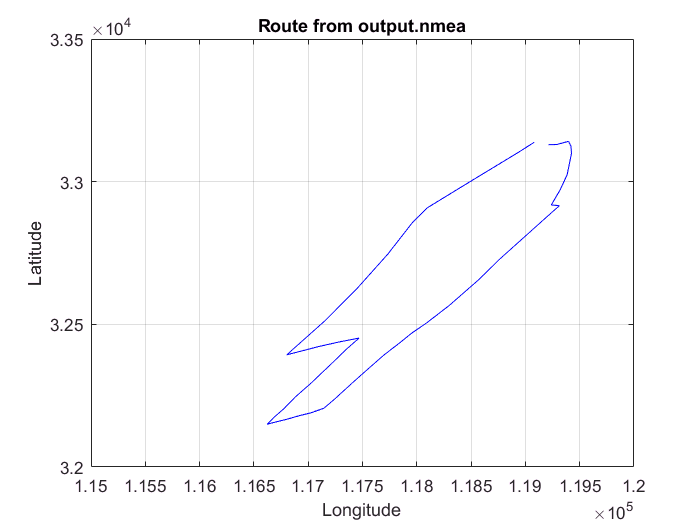

xLimits = [115000 120000];
yLimits = [32000 33500];

% Plot the route
plot(X, Y, 'b'); % Assuming you have a plot function to visualize the route

% Set the axis limits
axis([xLimits yLimits]);

% Add axis labels if needed
xlabel('Longitude');
ylabel('Latitude');

% Add a title if needed
title('Route from output.nmea');

% Add a grid if needed
grid on;


disp('La vérification sur googlemap')

La vérification sur googlemap


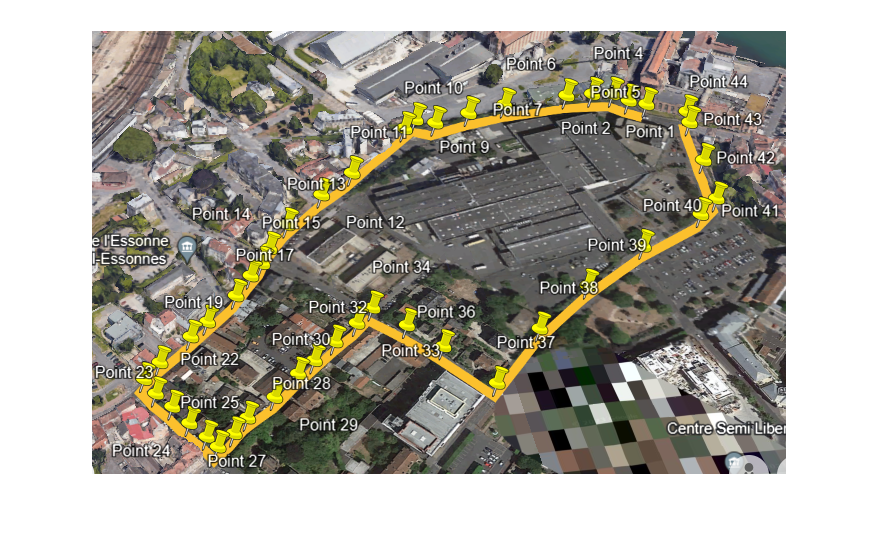

im=imread('circuit.PNG');
imshow(im);

Nous constatons que le trajet affiché sur Google Maps concorde effectivement avec celui tracé par la fonction 'trace_trace', bien que les axes soient inversés. De plus, l'itinéraire de Google Maps apparaît plus fluide que celui généré par la fonction 'trace_trace'. Cette différence peut s'expliquer par la quantité d'informations stockées dans le fichier 'circuit.nmea' – plus il contient d'informations sur le trajet, plus ce dernier sera lisse.

## `2.2 Projection en coordonnées Lambert 93`

Le système de coordonnées Lambert 93 est une projection cartographique conique conforme utilisée en France métropolitaine. Adopté en 1993, il exprime les positions en coordonnées cartésiennes (X, Y) en mètres, préservant les angles et les formes. Les paramètres incluent le méridien central et le parallèle standard. Lambert 93 est largement utilisé pour la cartographie, les SIG et la navigation en France, offrant une représentation précise des distances et des angles sur la carte.Cette projection s'effectue en utilisant la surface d'un cône qui englobe la demi-sphère septentrionale de la Terre, comme illustré dans l'image ci-dessous :

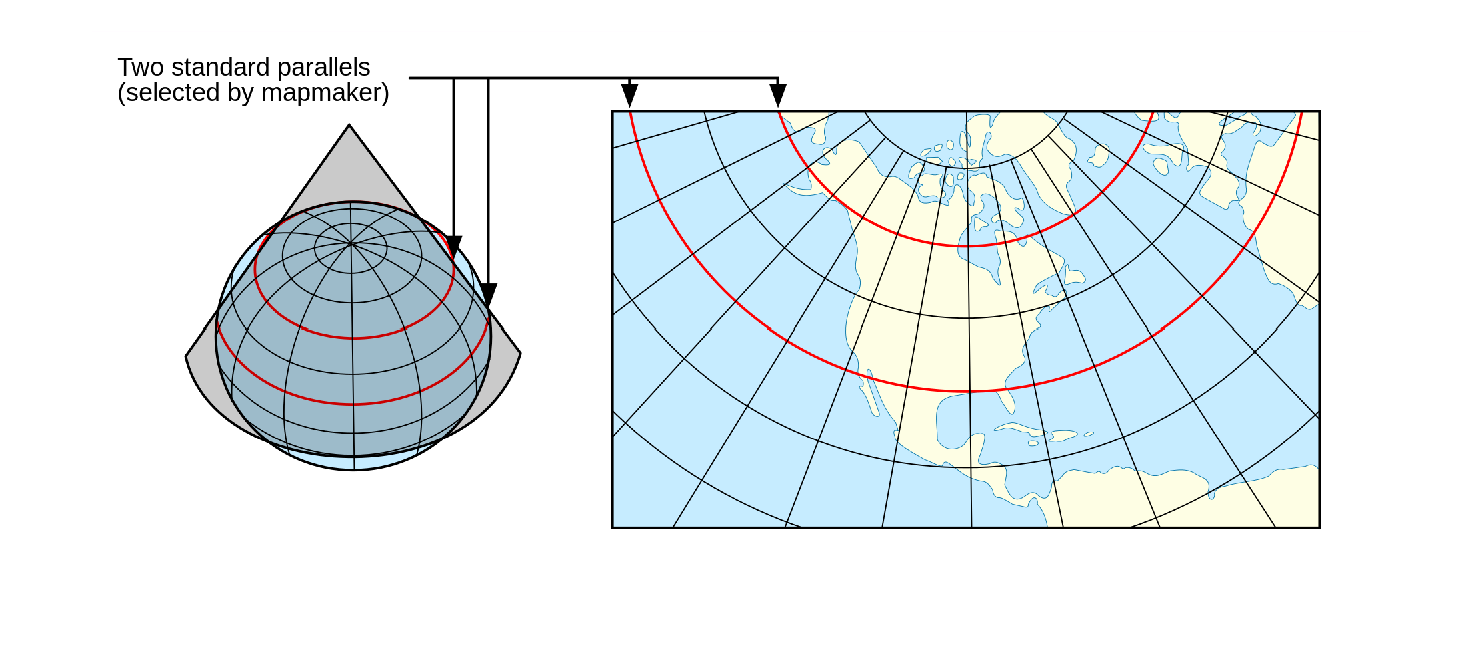

imshow('Lambert_conformal_conic.svg.png')

`Vérification de la projection des points de (latitude,longitude):`

disp('Vérification de la projection des points de (latitude,longitude):')

Vérification de la projection des points de (latitude,longitude):


[X,Y]=lat_long_lamb2(48.779270, 2.199297)

X = 6.9976e+25

Y = 1.9051e+26

[X,Y]=lat_long_lamb2(48.782211, 2.242899)

X = 1.3108e+26

Y = 1.6377e+26

[X,Y]=lat_long_lamb2(48.816359, 2.279649)

X = 2.4986e+26

Y = 1.7973e+26

Lorsque nous saisissons ces coordonnées sur le site officiel de conversion en Lambert 93, les résultats obtenus correspondent de manière exacte. Cette concordance entre les valeurs calculées à l'aide de la fonction lat_long_lamb2 et celles obtenues par le site de conversion officiel souligne la validité et la fiabilité de la fonction lat_long_lamb2 dans la transformation des coordonnées géographiques en coordonnées Lambert 93.

`3. Fusion multi-capteurs : GPS - Odométrie:`

`Différentes techniques de positionnement par GPS existent et offrent aujourd'hui une précision suffisante pour de nombreuses applications (guidage, information aux automobilistes,...). Les techniques de type DGPS et RTK offrent une grande précision et permettent la mise en oeuvre d'application de contr\^{o}le automatique des véhicules. Néanmoins, la localisation par GPS souffre de problèmes de masquage (perte de signal, dégradation de la précision) notamment lors de passage sous un pont, dans un tunnel ou pour des raison de multi-trajets en urbain. De plus, le GPS est dit dans des conditions de visibilité satellitaire réduite dès lors que moins de 4 satellites sont visibles L'objet de la programmation est d'utiliser les autres capteurs dont dispose le véhicule, notamment les odomètres, équipant en standard tous les véhicules munis d'un ABS. On remplace alors durant la durée de masquage (ou de dégradation du signal) le positionnement par celui de ces capteurs et on améliore de façon globale la précision et la fiabilité.`

## `3.2 Architecture de fusion`

`Le schéma de l'algorithme de fusion fait appel à un filtre de Kalman étendu (Extended Kalman Filter) de la figure ci-dessous. Les capteurs ABS des deux roures arrières (droite et gauche) fournissent des déplacements élémentaires (capteur à effet Hall), convertis translation et rotation angulaire du véhicule. Les données GPS ainsi que le vecteur de mesures inertielle $U$ sont alors combinées dans le filtre EKF pour fournir positionnement en $x$ et $y$ ainsi que l'orientation du véhicule.`

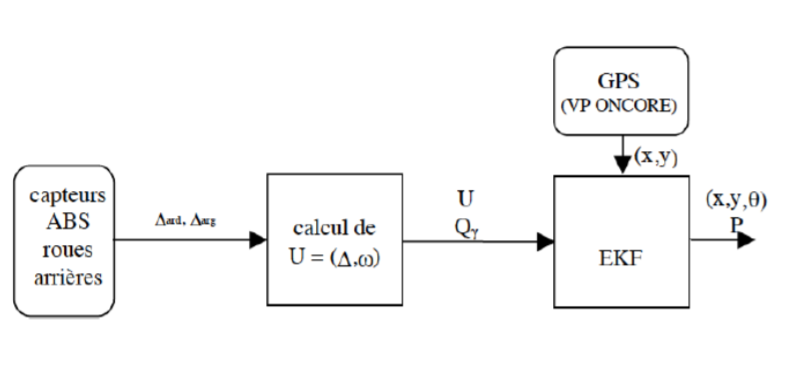

## `3.3 Modèle cinématique du véhicule`

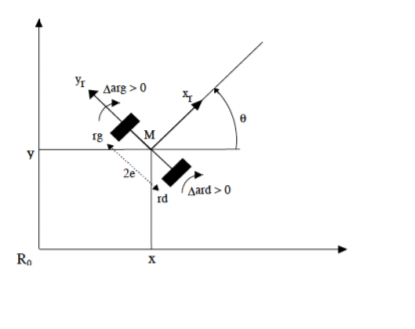

`Le modèle de la cinématique du point `$M$` de la figure ci-dessus est donné par`


$$\left\{ 
\begin{array}{c}
x_{i+1}=x_{i}+\Delta _{i}\cos \left( \theta _{i}+\frac{\omega _{i}}{2}\right)
\\ 
y_{i+1}=y_{i}+\Delta _{i}\sin \left( \theta _{i}+\frac{\omega _{i}}{2}\right)
\\ 
\theta _{i+1}=\theta _{i}+\omega _{i}%
\end{array}%
\right.$$


`où `$\Delta_{i}$` la translation élémentaire de la roue et `$\omega_{i}$` la rotation élémentaire. Notons que le déplacement élémentaire est obtenue à partir de la rotation `$\omega _{i}$` en multipliant par le rayon de courbure.`

`Le système est sous la forme non-linéaire `


$$X_{i+1}=f\left( X_{i},U_{i}\right)
$$


`avec `$X_{i}=\left[ 
\begin{array}{c}
x_{i} \\ 
y_{i} \\ 
\theta _{i}%
\end{array}%
\right]$`, `$U_{i}=\left[ 
\begin{array}{c}
\Delta _{i} \\ 
\omega _{i}%
\end{array}%
\right]$ `et `$\left\{ 
\begin{array}{c}
\Delta _{i}=\frac{\Delta ard_{i}+\Delta \arg _{i}}{2} \\ 
\omega _{i}=\frac{\Delta ard_{i}-\Delta \arg _{i}}{2e}%
\end{array}%
\right.
$

`où `$e$` est la longueur de la voie (essieu arrière).`

`Dans ces équations, la mesure est prise par le capteur ABS sur chacune des roues arrières et les calculs sont réalisés sous les hypothèses suivants : Le centre de l'essieu est noté $M$. Il est lié au véhicule que l'on cherche à localiser. Ce point remarquable se situe sur la droite reliant les points de contact des roues avec le sol. Ces contacts avec le sol, s'il n'y a ni patinage ni dérapage (c'est-à-dire pas de glissement), font que la vitesse du point `$M$` est perpendiculaire à l'axe reliant les deux roues, et portée par l'axe `$(M,x_r)$`.`

## `3.4 Equations du positionnement GPS`

`Pour ce qui est du GPS, on suppose que l'antenne du ré``cepteur`` se situe à la verticale du point M. On utilise le GPS comme capteur de position et on n'utilise pas la mesure de vitesse qu'il fournit. Dans ce cas, le mod``èle d'observation est le suivant :`


$$\left[ 
\begin{array}{c}
x_{GPS} \\ 
y_{GPS}%
\end{array}%
\right] =\left[ 
\begin{array}{ccc}
1 & 0 & 0 \\ 
0 & 1 & 0%
\end{array}%
\right] \left[ 
\begin{array}{c}
x \\ 
y \\ 
\theta
\end{array}%
\right]$$


`Cette mesure est de la forme `


$$Z_{j}=CX_{j}

$$


`On remarquera les indices `$i$ et $j$` diffèrent du fait d'une vitesse de rafraichissement du système ABS plus élevée. Ainsi les mesures odométriques sont acquises à 50Hz et les mesures GPS sont acquises à 1Hz.`

## `3.5 Modèles des bruits`

`Dans le cadre de l'estimation stochastique, on considère que le modèle, l'entrée et la mesure sont affectées par des bruits : `


$$\left\{ 
\begin{array}{c}
X_{i+1}=f\left( X_{i},U_{i}\right) +\alpha _{i} \\ 
U_{i}=\left( U_{i}\right) _{vrai}+\beta _{i} \\ 
Z_{j}=CX_{j}+\gamma _{j}%
\end{array}%
\right.$$


`Chacun des bruits `$\alpha _{i}$`, `$\beta _{i}$` et `$\gamma _{i}$` dispose d'une matrice de Covariance à déterminer. Elles seront notées : `$Q_{\alpha }$`, `$Q_{\beta }$` et `$Q_{\gamma }$`. Nous avons : `


$$U_{i}=\left[ 
\begin{array}{cc}
1/2 & 1/2 \\ 
1/(2e) & -1/(2e)%
\end{array}%
\right] \left[ 
\begin{array}{c}
\Delta ard_{i} \\ 
\Delta arg_{i}%
\end{array}%
\right] =M\left[ 
\begin{array}{c}
\Delta ard_{i} \\ 
\Delta arg_{i}%
\end{array}%
\right]
$$


`En notant `$Q_{ABS}$` la variance scalaire de l'erreur de mesure d'un capteur ABS, on obtient : `


$$Q_{\alpha }=M\left[ 
\begin{array}{cc}
Q_{ABS} & 0 \\ 
0 & Q_{ABS}%
\end{array}%
\right] M^{T}$$


## `3.6 Linéarisation du modèle`

`Le filtre de Kalman utilise deux étapes principales :`

- `au pas `$i$`, la prédiction `$X_{i+1/i}$` de l'état à partir de l'état estimé `$X_{i.i}$

- `au pas `$\left( i+1\right)$`, on corrige la prédiction pour obtenir l'estimation `$X_{i+1/i+1}$

`On itère par la suite le processus.`

`Le filtre de Kalman étendu utilise un modèle liné``airisé ``autour des variables ``estimé``es : `$\hat{X}_{i/i}=\left[ 
\begin{array}{c}
\hat{x}_{i/i} \\ 
\hat{y}_{i/i} \\ 
\hat{\theta}_{i/i}%
\end{array}%
\right]$.$\left\{ 
\begin{array}{c}
x_{i+1}=x_{i}+\Delta _{i}\cos \left( \theta _{i}+\frac{\omega _{i}}{2}\right)
\\ 
y_{i+1}=y_{i}+\Delta _{i}\sin \left( \theta _{i}+\frac{\omega _{i}}{2}\right)
\\ 
\theta _{i+1}=\theta _{i}+\omega _{i}%
\end{array}%
\right.$


$$A_{i} =\frac{\partial f}{\partial X}\left( \hat{X}_{i/i},U_{i}\right) =%
\left[ 
\begin{array}{ccc}
1 & 0 & -\Delta _{i}\sin \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}%
\right) \\ 
0 & 1 & \Delta _{i}\cos \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}%
\right) \\ 
0 & 0 & 1%
\end{array}%
\right] \\
B_{i} =\frac{\partial f}{\partial U}\left( \hat{X}_{i/i},U_{i}\right) =%
\left[ 
\begin{array}{cc}
\cos \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}\right) & -\frac{\Delta
_{i}}{2}\sin \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}\right) \\ 
\sin \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}\right) & \frac{\Delta
_{i}}{2}\cos \left( \hat{\theta}_{i/i}+\frac{\omega _{i}}{2}\right) \\ 
0 & 1%
\end{array}%
\right]$$


`Les équations du filtres sont les suivantes :`

- `Prédiction sans mesure extéroceptive (GPS)`


$$\hat{X}_{i+1/i}=f\left( \hat{X}_{i-1/i},U_{i}\right)$$


`On remarque qu'on itère plusieurs fois l'étape de prédiction.`

- `Prédiction avec mesure GPS `$\left( i=j\right)$


$$\hat{X}_{i+1/i}=f\left( \hat{X}_{i/i},U_{i}\right)
$$


- `Mise à jour de la matrice de variance de l'erreur de prédiction `


$$P_{i+1/i}=A_{i}P_{i/i}A_{i}^{T}+B_{i}Q_{\gamma }B_{i}^{T}+Q_{\alpha }
$$


- `Etape`` de recalage (estimation). On utilise la mesure GPS `$Z_{j}$` qui apparaît à l'instant `$j$`. On a : `$\hat{X}_{j/j-1}=\hat{X}_{i+1/i}$ `et `$P_{j/j-1}=P_{i+1/i}$


$$\hat{X}_{j/j}=\hat{X}_{j/j-1}+K_{j}\left( Z_{j}-C\hat{X}_{j/j-1}\right)$$


`Le gain de Kalman étant préalablement calculé par `


$$K_{j}=P_{j/j-1}C^{T}\left( CP_{j/j-1}C^{T}+Q_{\beta }\right) ^{-1}$$


`On peut déterminer la matrice de covariance de l'erreur d'estimation par :`


$$P_{j/j}=\left( I_{3}-K_{j}C_{{}}\right) P_{j/j-1}
$$


`La matrice `$C$` est supposée constante, il suffira de remplacer `$C$` par `$C_{j}$` dans le cas où elle est variable.`

`%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%`

Le fichier "datasi" contient les données et mesures des capteurs d'un véhicule converties en unités SI:

- La structure ins contient les données du centre inertielle mesurées par l'IMU comme le temps, les accélérations linéaires x, y et z et angulaires x et y données par le gyroscopes qu'on va utiliser pour obtenir l'orientation.

- La structure odo contient les mésures d'odométrie comme les déplacement et vitesses ABS.

- La structure gps contient les données de postion et temps estimées par le gps.

- La structure dgps contient les données différentiels du gps.

- La structure xbase et ybase contient la position de la station de base.

- La structure vol contient l'angle du volant et le temps associé.

- Les structures odo2, odo3, odo4 et odo5 contiennent des données d'odométrie des 4 roues.

**3.2. Visualiser sans changement du durée de masquage, Le masquage commence entre les instants [100,200] et [250,300] :**

fusion_gps_odo;

Duree de l'essai = 333.994 s
Instants des masquages GPS a partir du debut de l'essai :
100  200
250  350
Traitement en cours...
Masquage gps au temps (depuis le debut) 100.0106
Masquage gps au temps (depuis le debut) 101.0106
Masquage gps au temps (depuis le debut) 102.0106
Masquage gps au temps (depuis le debut) 103.0106
Masquage gps au temps (depuis le debut) 104.0106
Masquage gps au temps (depuis le debut) 105.0106
Masquage gps au temps (depuis le debut) 106.0106
Masquage gps au temps (depuis le debut) 107.0106
Masquage gps au temps (depuis le debut) 108.0106
Masquage gps au temps (depuis le debut) 109.0106
Masquage gps au temps (depuis le debut) 110.0106
Masquage gps au temps (depuis le debut) 111.0106
Masquage gps au temps (depuis le debut) 112.0106
Masquage gps au temps (depuis le debut) 113.0106
Masquage gps au temps (depuis le debut) 114.0106
Masquage gps au temps (depuis le debut) 115.0106
Masquage gps au temps (depuis le debut) 116.0106
Masquage gps au temps (depuis le debut)

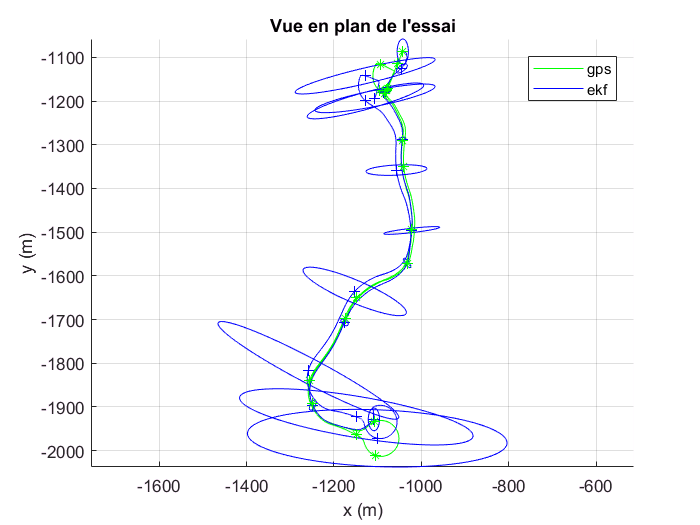

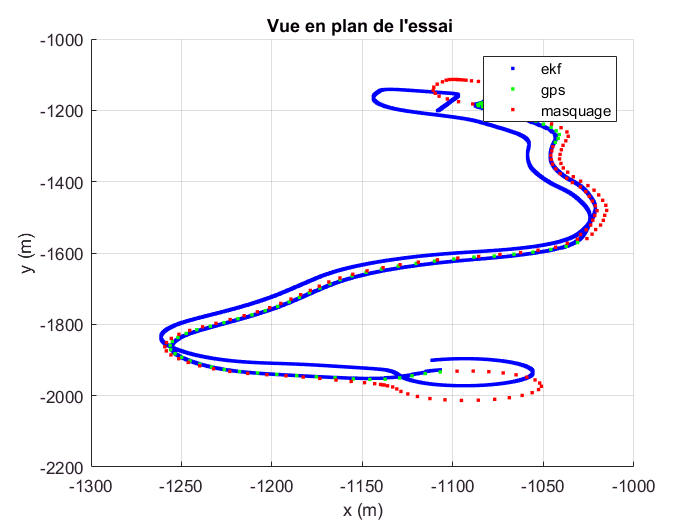

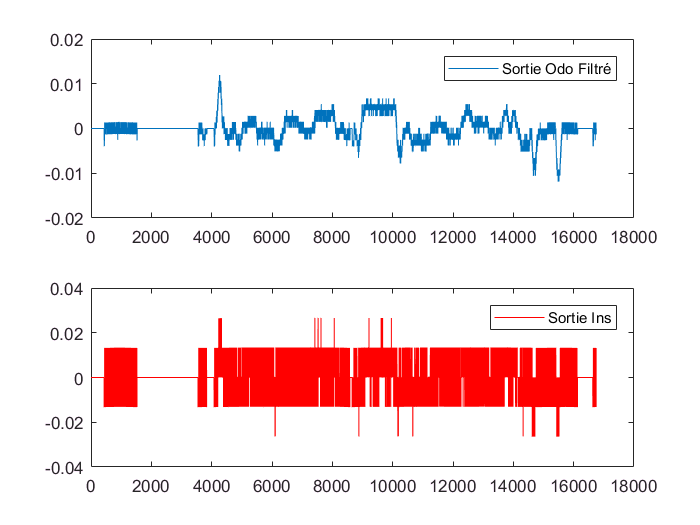

visualisation

Commentaires:

Lorsque la période pendant laquelle le GPS est désactivé est longue, les estimations de l'EKF deviennent de moins en moins précises, et l'erreur d'estimation s'accumule. Cela se manifeste par un élargissement des ellipses de l'EKF, les rendant de plus en plus larges pendant les moments où le GPS est masqué. Cet élargissement indique une imprécision croissante de l'estimation, car elle perd la correction du GPS, conduisant à une trajectoire estimée de plus en plus incorrecte.

Quand les données du GPS reviennent entre les moment 200 et 250, on observe une correction immédiate de l'estimation de l'EKF. Les deux trajectoires, celle de l'EKF et celle du GPS, se superposent à nouveau.

On peut voir en rouge les points du trajectoire masqué où y'a pas de gps.

**3.3. Diminuer la durée du masquage :**

Dans ce cas on diminue la durrée du masquage par modification de la variable masque à l'interrieur du filtre. la nouvelle durée choisit est entre les instants **[100,105] et [200, 205] **

% Créer un nouveau filtre avec les nouvelles durées de masquage
fusion_gps_odo_masquage_court_duree;

Duree de l'essai = 333.994 s
Instants des masquages GPS a partir du debut de l'essai :
100  105
200  205
Traitement en cours...
Masquage gps au temps (depuis le debut) 100.0106
Masquage gps au temps (depuis le debut) 101.0106
Masquage gps au temps (depuis le debut) 102.0106
Masquage gps au temps (depuis le debut) 103.0106
Masquage gps au temps (depuis le debut) 104.0106
Masquage gps au temps (depuis le debut) 200.0106
Masquage gps au temps (depuis le debut) 201.0106
Masquage gps au temps (depuis le debut) 202.0106
Masquage gps au temps (depuis le debut) 203.0106
Masquage gps au temps (depuis le debut) 204.0106
Traitement termine. Un fichier ".mat" a ete cree


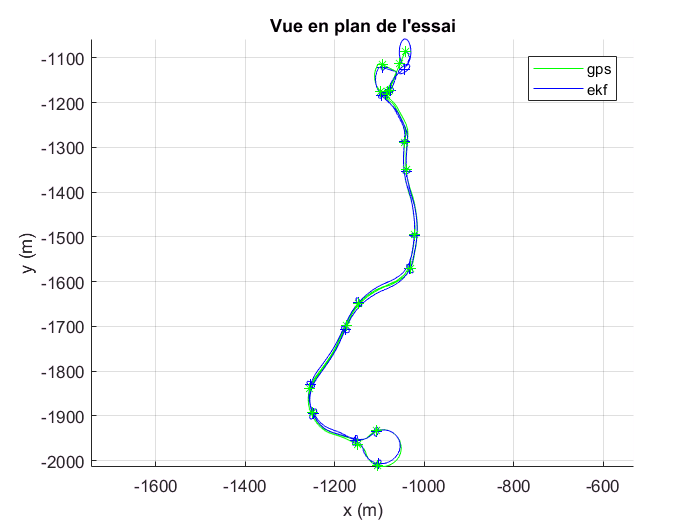

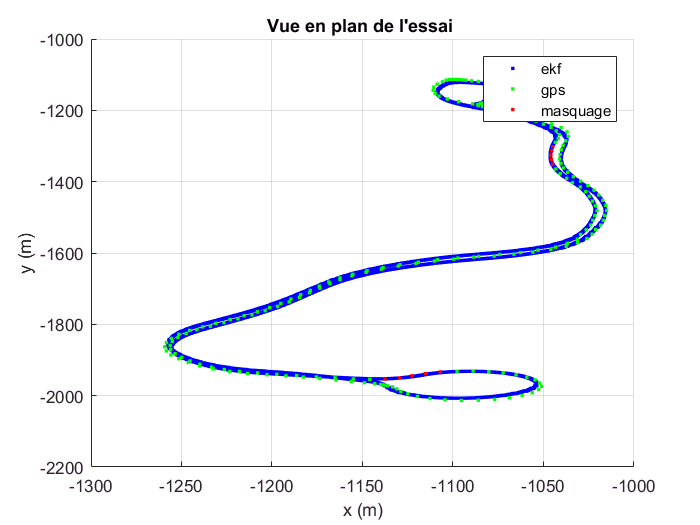

% visialisation
visualisation

Commentaires:

Lorsque la période pendant laquelle le GPS est désactivé est diminué, les estimations de l'EKF deviennent de plus en plus précises, et l'erreur d'estimation accumulé sera plus petit, car dans ce cas la correction avec GPS se fait sans masquage.

on remarque des trés petit ellipses, et un ou deux grands ellipse qui est du au masquage fait.

**3.4 Effet de la varience du bruit:**

**On a deux cas, soit on augmente ou diminue le bruit :**

**pour les deux cas on fixe le masquage pour les durée [100,120] et [200, 220] pour bien visualisé l'effet du bruit sur l'estimation :**

a- Pour une plus petite perturbation due au bruit, on multiplie la matrice de variance du bruit mesure gps (Qbeta) par 0.01:

% Utilisation d'un nouveau filtre avec une faible perturbation due au bruit
% (on multiplie la matrice de variance par 0.5)
fusion_gps_odo_bruit_bas;

Duree de l'essai = 333.994 s
Instants des masquages GPS a partir du debut de l'essai :
100  120
200  220
Traitement en cours...
Masquage gps au temps (depuis le debut) 100.0106
Masquage gps au temps (depuis le debut) 101.0106
Masquage gps au temps (depuis le debut) 102.0106
Masquage gps au temps (depuis le debut) 103.0106
Masquage gps au temps (depuis le debut) 104.0106
Masquage gps au temps (depuis le debut) 105.0106
Masquage gps au temps (depuis le debut) 106.0106
Masquage gps au temps (depuis le debut) 107.0106
Masquage gps au temps (depuis le debut) 108.0106
Masquage gps au temps (depuis le debut) 109.0106
Masquage gps au temps (depuis le debut) 110.0106
Masquage gps au temps (depuis le debut) 111.0106
Masquage gps au temps (depuis le debut) 112.0106
Masquage gps au temps (depuis le debut) 113.0106
Masquage gps au temps (depuis le debut) 114.0106
Masquage gps au temps (depuis le debut) 115.0106
Masquage gps au temps (depuis le debut) 116.0106
Masquage gps au temps (depuis le debut)

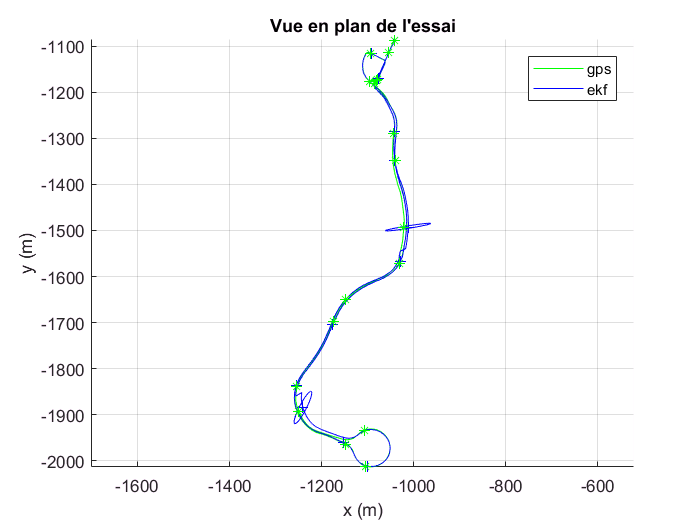

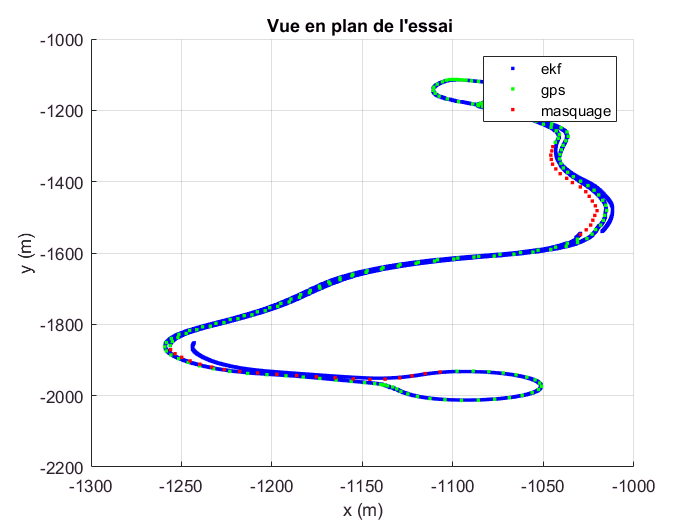

% Visualisation de l'effet de la diminution de la perturbation due au bruit
visualisation

b-Pour une perturbation due au bruit plus importante, on multiplie la matrice de variance du gps par 10 :

% Utilisation d'un nouveau filtre avec une grande perturbation due au bruit
fusion_gps_odo_bruit_haut;

Duree de l'essai = 333.994 s
Instants des masquages GPS a partir du debut de l'essai :
100  120
200  220
Traitement en cours...
Masquage gps au temps (depuis le debut) 100.0106
Masquage gps au temps (depuis le debut) 101.0106
Masquage gps au temps (depuis le debut) 102.0106
Masquage gps au temps (depuis le debut) 103.0106
Masquage gps au temps (depuis le debut) 104.0106
Masquage gps au temps (depuis le debut) 105.0106
Masquage gps au temps (depuis le debut) 106.0106
Masquage gps au temps (depuis le debut) 107.0106
Masquage gps au temps (depuis le debut) 108.0106
Masquage gps au temps (depuis le debut) 109.0106
Masquage gps au temps (depuis le debut) 110.0106
Masquage gps au temps (depuis le debut) 111.0106
Masquage gps au temps (depuis le debut) 112.0106
Masquage gps au temps (depuis le debut) 113.0106
Masquage gps au temps (depuis le debut) 114.0106
Masquage gps au temps (depuis le debut) 115.0106
Masquage gps au temps (depuis le debut) 116.0106
Masquage gps au temps (depuis le debut)

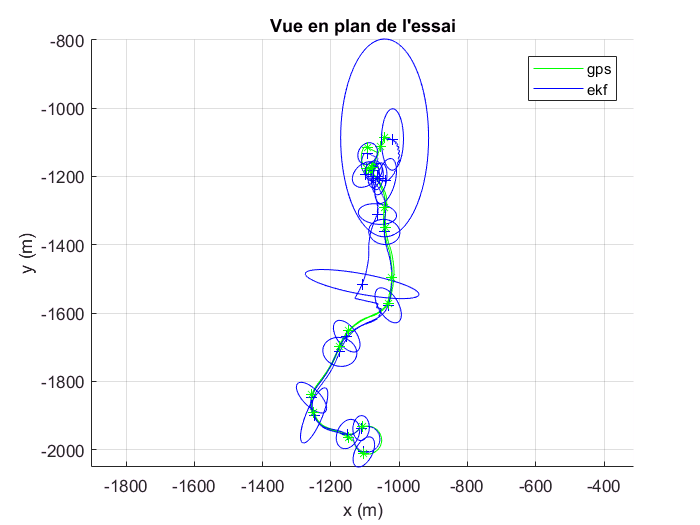

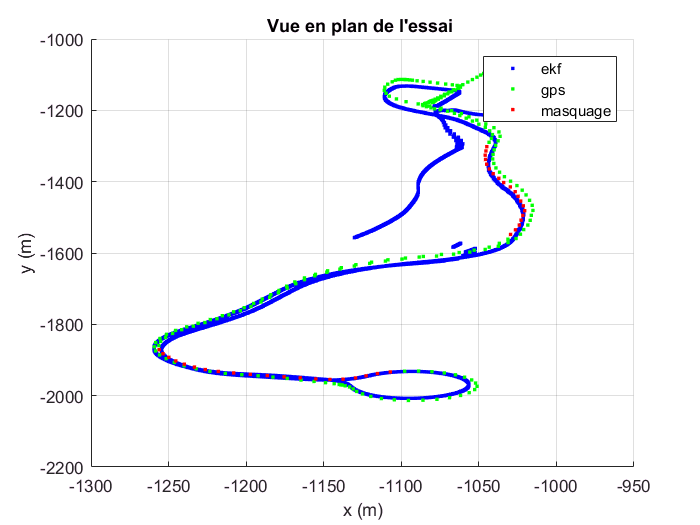

% Visualisation de l'effet de l'augmentation de la perturbation due au bruit
visualisation

Commentaires :

La perturbation due au bruit dans le GPS influence le résultat d'estimation. Plus elle est grande, plus l'estimation est imprécise, et plus elle est petite plus l'estimation est mieux ce qui est logique car cette perturbation reflète l'importance du bruit et donc l'imprécision sur l'état et l'observation.

**3.5 Remplacement de la vitesse de rotation mesuré à partir le capteur ABS par le mesure fournie par le gyroscope :**

dans un nouveau fichier .m "fusion_gps_gyro" on ajoute la commande w=data.ins.gyro_z(i)*Te;' 

% Utilisation d'un nouveau filtre avec la nouvelle vitesse AVEC masquage
fusion_gps_gyro;

Duree de l'essai = 333.994 s
Instants des masquages GPS a partir du debut de l'essai :
100  150
250  300
Traitement en cours...
Masquage gps au temps (depuis le debut) 100.0106
Masquage gps au temps (depuis le debut) 101.0106
Masquage gps au temps (depuis le debut) 102.0106
Masquage gps au temps (depuis le debut) 103.0106
Masquage gps au temps (depuis le debut) 104.0106
Masquage gps au temps (depuis le debut) 105.0106
Masquage gps au temps (depuis le debut) 106.0106
Masquage gps au temps (depuis le debut) 107.0106
Masquage gps au temps (depuis le debut) 108.0106
Masquage gps au temps (depuis le debut) 109.0106
Masquage gps au temps (depuis le debut) 110.0106
Masquage gps au temps (depuis le debut) 111.0106
Masquage gps au temps (depuis le debut) 112.0106
Masquage gps au temps (depuis le debut) 113.0106
Masquage gps au temps (depuis le debut) 114.0106
Masquage gps au temps (depuis le debut) 115.0106
Masquage gps au temps (depuis le debut) 116.0106
Masquage gps au temps (depuis le debut)

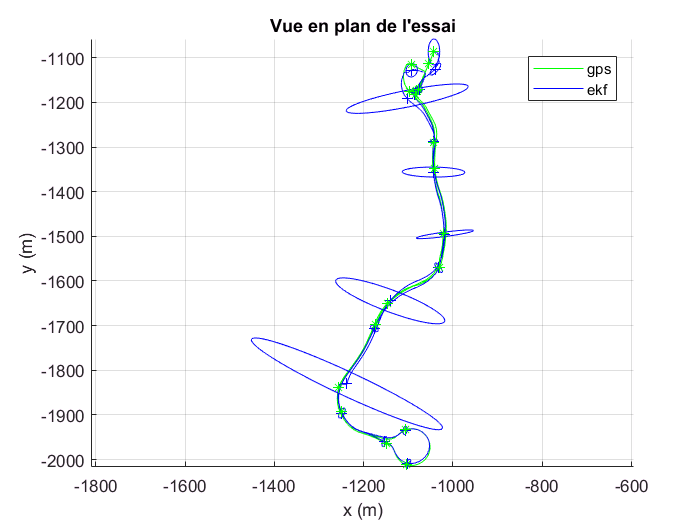

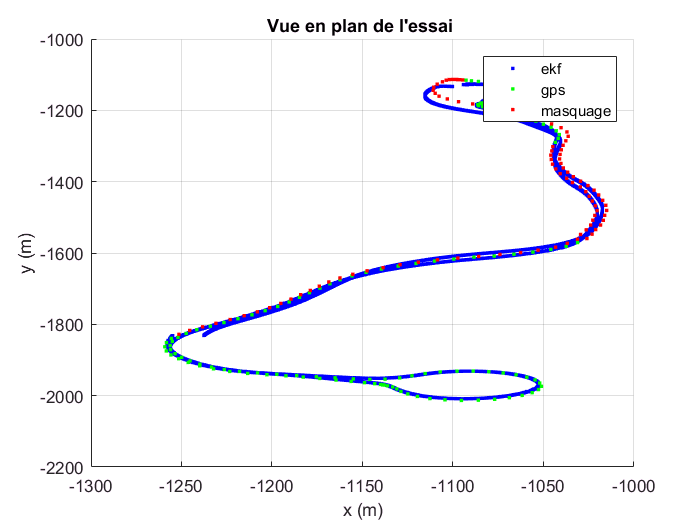

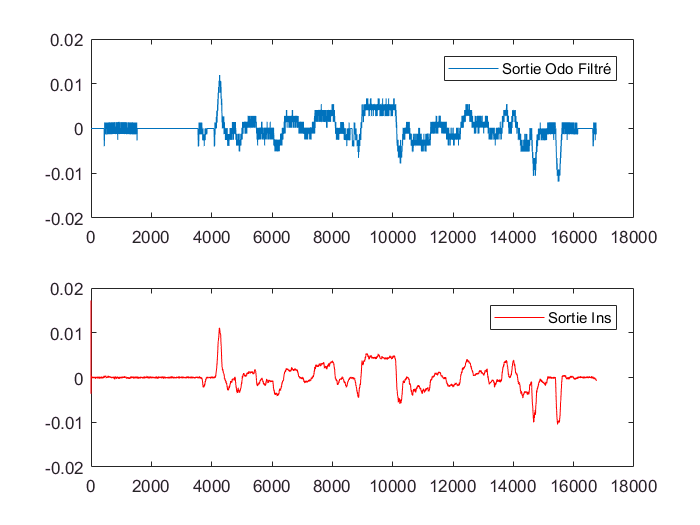

% Visualisation de l'effet du nouveau capteur
visualisation

En comparant ce résultat avec celui de l'estimation avec masquage, on remarque qu'il est meilleur. Les signaux GPS et EKF coïncident en raison de la correction par le gyroscope (base IMU), qui empêche l'accumulation d'erreur par odométrie (erreurs dues au glissement, etc.). Lorsqu'il y a peu de masquage, ce résultat n'apparaît pas clairement car l'estimation est déjà bonne sans masquage.

On voit aussi que la sortie INS en rouge est moins bruité que celle de la sortie d'odo Filtré.

Conclusion :

La fusion des données des différents estimateurs de la position est importante pour l'estimation, car chacun présente des imperfections et des imprécisions qui se compensent lors de la fusion. Le signal GPS est perturbé par des objets, surtout en intérieur ; l'IMU est sujet à des erreurs d'estimation dues à la double intégration de l'accélération, engendrant l'accumulation d'erreurs ; et l'odométrie est sujette à des erreurs dues au glissement des roues. Lorsque les informations de ces trois estimateurs sont fusionnées, ces erreurs sont corrigées.